warning off;
img1_path = 'child.jpg';
img2_path = 'zqf.jpg';
img1 = imgPre(img1_path);
img2 = imgPre(img2_path);

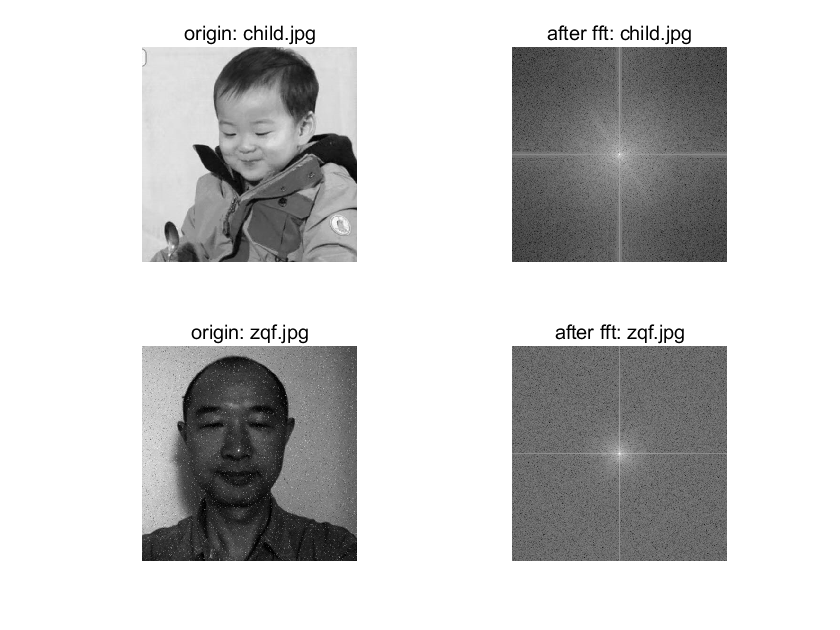

% FFT and dislplay
[d_img1, f_img1] = imgFFT(img1);
[d_img2, f_img2] = imgFFT(img2);
subplot(2, 2, 1), imshow(img1, []), title(['origin: ', img1_path]);
subplot(2, 2, 2), imshow(d_img1, []), title(['after fft: ', img1_path]);
subplot(2, 2, 3), imshow(img2, []), title(['origin: ', img2_path]);
subplot(2, 2, 4), imshow(d_img2, []), title(['after fft: ', img2_path]);

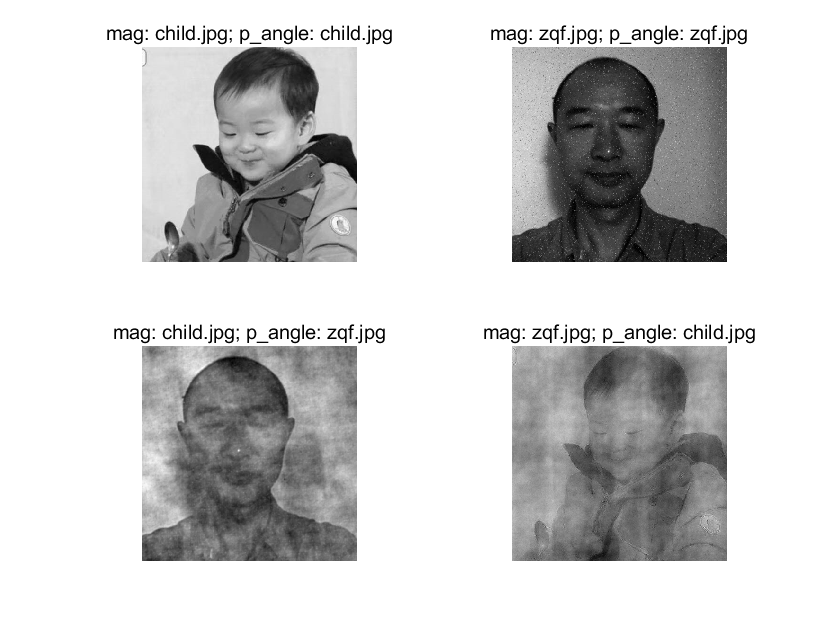

% exchange
m1pa1_img = imgRestructIfft(f_img1, f_img1);
m2pa2_img = imgRestructIfft(f_img2, f_img2);
m1pa2_img = imgRestructIfft(f_img1, f_img2);
m2pa1_img = imgRestructIfft(f_img2, f_img1);
subplot(2, 2, 1), imshow(m1pa1_img, []), title(['mag: ', img1_path,'; p\_angle: ', img1_path]);
subplot(2, 2, 2), imshow(m2pa2_img, []), title(['mag: ', img2_path,'; p\_angle: ', img2_path]);
subplot(2, 2, 3), imshow(m1pa2_img,[]), title(['mag: ', img1_path,'; p\_angle: ', img2_path]);
subplot(2, 2, 4), imshow(m2pa1_img,[]), title(['mag: ', img2_path,'; p\_angle: ', img1_path]);